clc
clear
cls

sat = readSC('flatCone.obj',1)

Reading Object file : flatCone.obj
  % Blender v2.83.1 OBJ File: 'flatCone.blend'
  %www.blender.org
Reading Material file : flatCone.mtl
  % Blender MTL File: 'flatCone.blend'
  % Material Count: 1
Finished Reading Material file
Finished Reading Object file


ans =    481     3


ans =    800     3


sat = フィールドをもつ struct :
    vertices: [481×3 double]
       faces: [800×3 double]
        area: [800×1 double]
         pos: [800×3 double]
      normal: [800×3 double]
          Ca: [800×1 double]
          Cd: [800×1 double]
          Cs: [800×1 double]


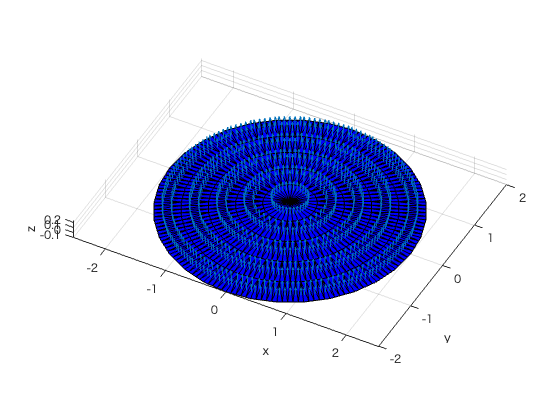

showSC(sat)


nFacet = size(sat.area,1);
sat.mCT = 0.2;
sat.F0 = 0.5

sat = フィールドをもつ struct :
    vertices: [481×3 double]
       faces: [800×3 double]
        area: [800×1 double]
         pos: [800×3 double]
      normal: [800×3 double]
          Ca: [800×1 double]
          Cd: [800×1 double]
          Cs: [800×1 double]
         mCT: 0.200000000000000
          F0: 0.500000000000000


sat.rho = 0.5;

## parameters

const = orbitConst;
d = au2km(1.0, const) * 10^3; % m, distance from sat to sun
dAU = km2AU(d ./ 10^3, const); % AU
S0 = const.S0; % Solar constant, W/m^2
c = const.c; % light speed, m/s
coeff = -S0 / c / dAU^2;


illumination condition

phiI = deg2rad(10);
thetaI = deg2rad(20);
sunB = [sin(thetaI)*cos(phiI), sin(thetaI)*sin(phiI),  cos(thetaI)];
NS = sat.normal * sunB';
sunlitFlag = (sat.normal * sunB' > 0); % nFacetx1 matrix, 1: sunlit, 0: shade

[sat, srpCdOut, srpCsOut] = srpCT(sat, sunB, d, const, 'Gauss');

thetaN = acos(NS);
thetaN = thetaN(:);

for i = 1:nFacet
    srpApproxCT(sat, thetaN(i), sunB, d, const)
srpCsApprox(i,:) = srpApproxCT(sat, thetaN(i), sunB, d, const);
end

ans = 1.0e-08 *

  -0.000000000000084  -0.249612041297419  -0.310174891816000
  -0.000000000000084  -0.249612630880165  -0.310175624447982
  -0.000000000000084  -0.249613311581977  -0.310176470307059
  -0.000000000000084  -0.249613266782205  -0.310176414637610
  -0.000000000000084  -0.249613266782205  -0.310176414637611
  -0.000000000000084  -0.249610650499803  -0.310173163572050
  -0.000000000000084  -0.249611590002270  -0.310174331024048
  -0.000000000000084  -0.249612038178641  -0.310174887940519
  -0.000000000000084  -0.249612041297419  -0.310174891816000
  -0.000000000000084  -0.249615173135915  -0.310178783525958


左辺のインデックスが右辺とサイズが適合しないため、代入は実行できません。